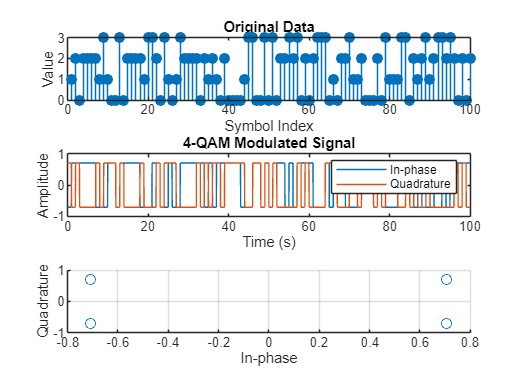

% Parameters
N = 100; % Number of symbols
data = randi([0 3], 1, N); % Generate random symbols (0, 1, 2, 3)
fs = 10000; % Sampling frequency in Hz
Ts = 1; % Symbol duration in seconds
t = 0:1/fs:Ts-1/fs; % Time vector for one symbol

% 4-QAM Modulation
qam_signal = [];
for i = 1:N
    switch data(i)
        case 0
            symbol = (1 + 1j) / sqrt(2); % Symbol for 00
        case 1
            symbol = (-1 + 1j) / sqrt(2); % Symbol for 01
        case 2
            symbol = (1 - 1j) / sqrt(2); % Symbol for 10
        case 3
            symbol = (-1 - 1j) / sqrt(2); % Symbol for 11
    end
    qam_signal = [qam_signal symbol * ones(1, length(t))]; % Append symbol to the signal
end

% Time vector for the entire signal
t_total = 0:1/fs:(N*Ts)-1/fs;

% Spectrum Analysis
qam_spectrum = fftshift(fft(qam_signal));
f = (-length(qam_spectrum)/2:length(qam_spectrum)/2-1)*(fs/length(qam_spectrum));

% Plotting
figure;
subplot(3,1,1);
stem(data, 'filled');
title('Original Data');
xlabel('Symbol Index');
ylabel('Value');

subplot(3,1,2);
plot(t_total, real(qam_signal));
hold on;
plot(t_total, imag(qam_signal));
title('4-QAM Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('In-phase', 'Quadrature');

subplot(3,1,3);
scatter(real(qam_signal),imag(qam_signal));
xlabel("In-phase");
ylabel("Quadrature");
xlabel("In-phase");
ylabel("Quadrature");
grid on;

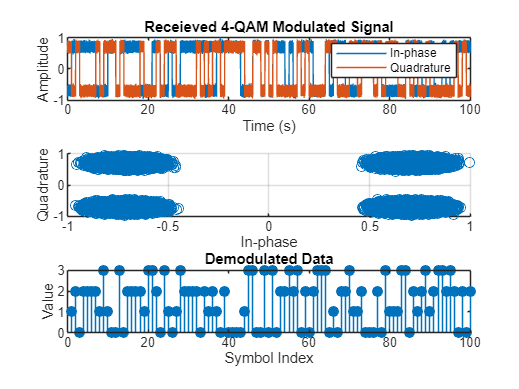

% Demodulation and Sampling
SNR = 22; % Signal-to-Noise Ratio in dB
received_signal = awgn(qam_signal, SNR, 'measured'); % Noisy received signal
demodulated_data = zeros(1, N);

for i = 1:N
    symbol = received_signal((i-1)*length(t) + 1); % Sample at the beginning of each symbol period
    if real(symbol) > 0 && imag(symbol) > 0
        demodulated_data(i) = 0; % 00
    elseif real(symbol) < 0 && imag(symbol) > 0
        demodulated_data(i) = 1; % 01
    elseif real(symbol) > 0 && imag(symbol) < 0
        demodulated_data(i) = 2; % 10
    else
        demodulated_data(i) = 3; % 11
    end
end

% Plotting demodulated data
figure;
subplot(3,1,1);
plot(t_total,real(received_signal));
hold on;
plot(t_total,imag(received_signal));
title('Receieved 4-QAM Modulated Signal With Noise');
xlabel('Time (s)');
ylabel('Amplitude');
legend("In-phase","Quadrature");

subplot(3,1,2);
scatter(real(received_signal),imag(received_signal));
xlabel("In-phase");
ylabel("Quadrature");
grid on;

subplot(3,1,3);
stem(demodulated_data, 'filled');
title('Demodulated Data');
xlabel('Symbol Index');
ylabel('Value');